# Laboratorium 1 - Repetytorium algebry liniowej  

#### Zadanie 1

Napisz funkcję umożliwiającą obliczanie iloczynu skalarnego oraz wektorowego dwóch wektorów. Wynikiem działania funkcji powinny być obliczone wartości wektorów oraz ilustracja wszystkich wektorów na wykresie. 

dot = -3

cross =      5     3   -29


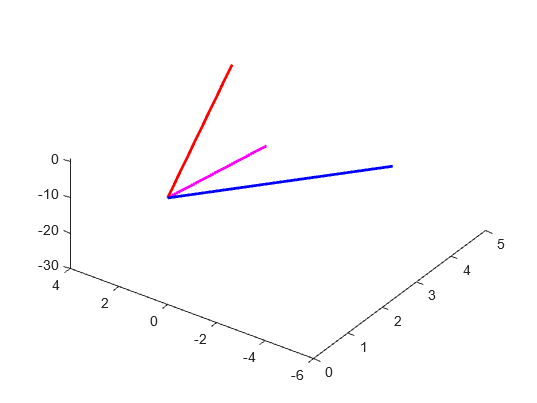

a = [4 3 1];
b = [3 -5 0];
iloczyn(a, b)

*Przydatne funkcje:*

plot3

#### Zadanie 2

Dane są proste w postaci równań: $A_1 x+B_1 y+C_1 =0$ oraz $A_2 x+B_2 y+C_2 =0$

Napisz funkcję o parametrach wejściowych $A_1 ,B_1 ,C_1 ,A_2 ,B_2 ,C_2 ,x_0 ,x_1 ,x_p ,y_p$ realizującej następujące operacje: 

- Narysuj wykresy tych prostych w przedziale $x\in \left\lbrack x_0 ,x_1 \right\rbrack$.

- Sprawdź czy te proste są: prostopadłe, równoległe, przecinające się, pokrywające się.  

- Oblicz odległość punktu $p\;\left(x_p ,y_p \right)$ od tych prostych.

- Oblicz odległość pomiędzy tymi prostymi (jeśli są równoległe). 

Zilustruj działanie funkcji dla zadanych prostych:

- prostopadłych,

- równoległych,

- przecinających się,

- pokrywających się.

*Wskazówki:*

Równanie ogólne prostej: $A\;x+B\;y+C=0$

Odległość punktu od prostej: $d=\frac{\left|A\;x_p +B\;y_p +C\right|}{\sqrt{A^2 +B^2 }}$

Odległość dwóch prostych równoległych: $d=\frac{\left|C_2 -C_1 \right|}{\sqrt{A^2 +B^2 }}$

Warunek prostopadłości: $A_1 \;A_2 +B_1 \;B_2 =0$

Warunek równoległości: $\det \left\lbrack \begin{array}{cc}
A_1  & B_1 \\
A_2  & B_2 
\end{array}\right\rbrack =0$

Warunek pokrywania się: $\det \left\lbrack \begin{array}{cc}
A_1  & B_1 \\
A_2  & B_2 
\end{array}\right\rbrack =\;\det \;\left\lbrack \begin{array}{cc}
A_1  & C_1 \\
A_2  & C_2 
\end{array}\right\rbrack \;=0$

Warunek przecinania się: $\det \left\lbrack \begin{array}{cc}
A_1  & B_1 \\
A_2  & B_2 
\end{array}\right\rbrack \not= 0$

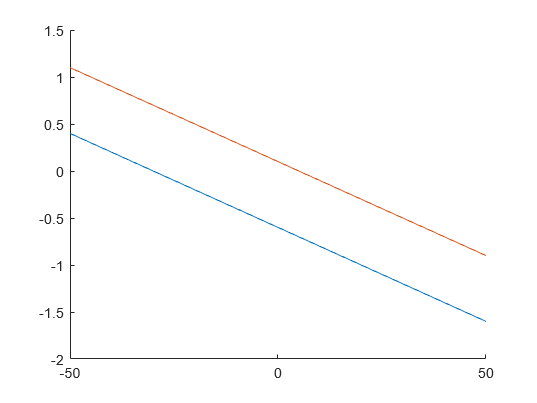

prostopadle = logical
   0


rownolegle = logical
   1


przecinaja = logical
   0


pokrywaja = logical
   0


odlegloscOdPunktu1 = 10.9978

odlegloscOdPunktu2 = 10.2979

odlegloscMiedzyProstymi = 0.6999

rysuj(2,100,60,2,100,-10,-50,50,20,10)

*Przydatne funkcje:*

fplot, disp, fprintf, abs

#### Zadanie 3

Narysuj na wykresie proste tworzące układ równań oraz określ i zaznacz rozwiązanie (jeśli istnieje) dla następujących przypadków układów równań:  

- Układ równań określony  $\begin{array}{l}
a_{11} {\;x}_1 +a_{12} {\;x}_2 =b_1 \\
a_{21} {\;x}_1 +a_{22} {\;x}_2 =b_2 
\end{array}$

- Układ równań nadokreślony  $\begin{array}{l}
a_{11} {\;x}_1 +a_{12} {\;x}_2 =b_1 \\
a_{21} {\;x}_1 +a_{22} {\;x}_2 =b_2 \\
a_{31} {\;x}_1 +a_{32} {\;x}_2 =b_3 
\end{array}$

Przyjmij parametry równania w postaci macierzowej: $A\;X=B$. Wybierz dogodne wartości macierzy $A$ oraz $B$ dla ilustracji rozwiązania.

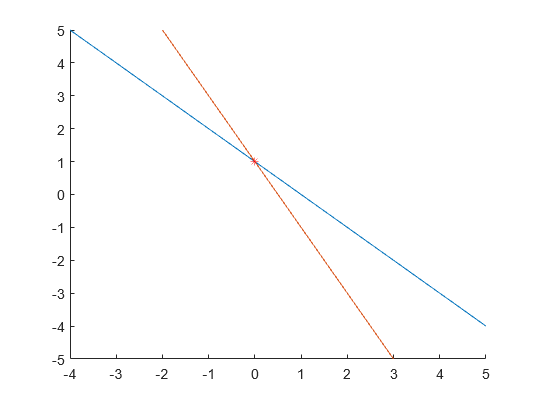

A = [1 1; 2 1];
B = [1; 1];

rownanie(A,B)

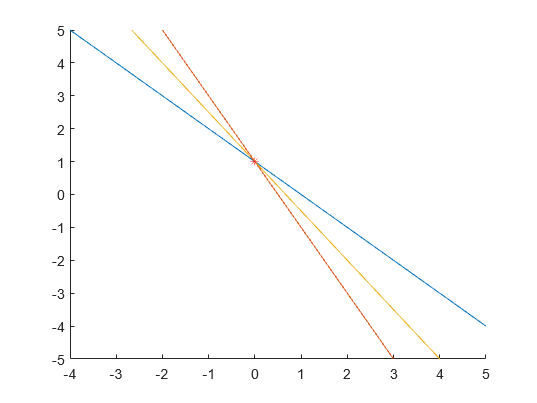

A = [1 1; 2 1; 3 2];
B = [1; 1; 2];

rownanie(A,B)

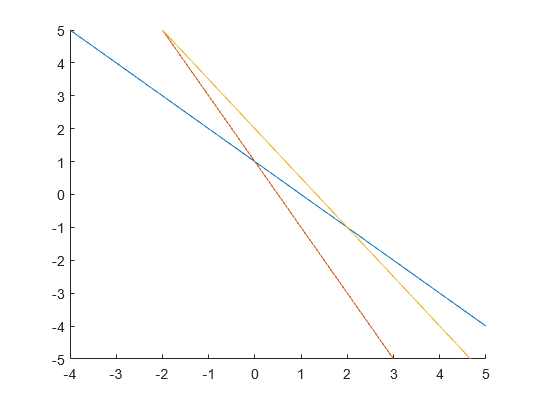

A = [1 1; 2 1; 3 2];
B = [1; 1; 4];

rownanie(A,B)

function iloczyn(a,b)
    i = [1 0 0];
    j = [0 1 0];
    k = [0 0 1];

    dot = a(1).*b(1)+a(2).*b(2)+a(3).*b(3)
    cross = i*(a(2)*b(3)-a(3)*b(2))+j*(a(3)*b(1)-a(1)*b(3))+k*(a(1)*b(2)-a(2)*b(1))

    clf;
    hold on;
    plot3([0 a(1)], [0 a(2)], [0 a(3)], 'r-', 'LineWidth', 2);
    plot3([0 b(1)], [0 b(2)], [0 b(3)], 'b-', 'LineWidth', 2);
    plot3([0 cross(1)], [0 cross(2)], [0 cross(3)], 'm-', 'LineWidth', 2);
    hold off;
end


function rysuj(A1,B1,C1,A2,B2,C2,x0,x1,xp,yp)
    prosta1 = @(x) (-A1/B1)*x - C1/B1;
    prosta2 = @(x) (-A2/B2)*x - C2/B2;

    clf;
    hold on;
    fplot(prosta1, [x0, x1]);
    fplot(prosta2, [x0, x1]);
    hold off;

    det1 = det([A1 B1; A2 B2]);
    det2 = det([A1 C1; A2 C2]);

    prostopadle = (A1.*A2 + B1.*B2 == 0)
    rownolegle = (det1 == 0)
    przecinaja = (det1 ~= 0)
    pokrywaja = (det1 == det2)&&(det1 == 0)

    odlegloscOdPunktu1 = abs(A1.*xp+B1.*yp+C1)/(sqrt(A1.*A1 + B1.*B1))
    odlegloscOdPunktu2 = abs(A2.*xp+B2.*yp+C2)/(sqrt(A2.*A2 + B2.*B2))
    if (rownolegle)
        odlegloscMiedzyProstymi = abs(C2 - C1)/(sqrt(A2.*A2 + B2.*B2))
    end
end

function rownanie(A,B)
    uklad = [];
    syms x1 x2;

    clf;
    hold on;
    for i = 1:size(A, 1)
        rownanie = A(i,:)*[x1;x2] - B(i);
        uklad = [uklad, rownanie];
    end
    fimplicit(uklad);
    rozwiazanie = solve(uklad);
    if ~isempty(rozwiazanie.x1) && ~isempty(rozwiazanie.x2)
        plot(rozwiazanie.x1, rozwiazanie.x2, 'r*');
    end;
    hold off;
end